# Compressing data

## Introduction

load weatherEindhoven.mat
timescale = 1:10*24*60;

### Techniques 

Compressing with DFT 

%normal compression using forier transform
N_norm = length(weatherEindhoven);
M_norm = 80000;              %must be an integer value
R_norm = N_norm/M_norm                %compression ratio

R_norm = 269.5500

%
%comment out the whole section if it is not needed
compressed = Compressed_FT(weatherEindhoven, M_norm);
decompressed = Decompress_FT(compressed,N_norm,M_norm);

%plotting the fourier transform
%plot(decompressed(timescale)), hold on;
%plot(weatherEindhoven(timescale))
print_stats(weatherEindhoven,compressed,decompressed)

R_sqr = 0.9996

avg_sqr_res = 0.0204

compression = 80000

ans = 80000

%}

`  To keep the compression ratio the same N_norm/M_norm = N_split/M_split`

`using that N_splits = L/n_splits and N_norm = L, it follows that`

`M_split = M_norm /n_splits`

n_splits = 2000;
N = length(weatherEindhoven)/n_splits %has to be an integer value

N = 10782

M_split = M_norm / n_splits %has to be an integer value

M_split = 40

%M = 2250 %manual overide
R = N / M_split %compression ratio

R = 269.5500

%
splitted_compressed = split_compressed_FFT(weatherEindhoven, n_splits,N,M_split);
splitted_decompressed = split_decompression(splitted_compressed,n_splits,N,M_split);
print_stats(weatherEindhoven,splitted_compressed,splitted_decompressed);

R_sqr = 0.9984

avg_sqr_res = 0.0823

compression = 80000

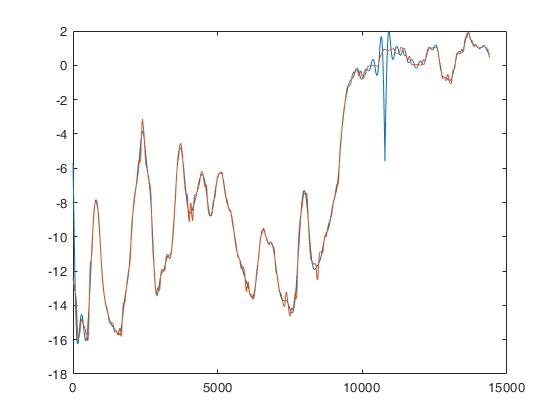

plot(splitted_decompressed(timescale)), hold on;
plot(weatherEindhoven(timescale))

%


%{
compression_stats(weatherEindhoven,2,M_norm);
compression_stats(weatherEindhoven,4,M_norm);
%
compression_stats(weatherEindhoven,10,M_norm);
compression_stats(weatherEindhoven,20,M_norm);
compression_stats(weatherEindhoven,40,M_norm);
compression_stats(weatherEindhoven,80,M_norm);
compression_stats(weatherEindhoven,100,M_norm);
compression_stats(weatherEindhoven,200,M_norm);
compression_stats(weatherEindhoven,500,M_norm);
compression_stats(weatherEindhoven,1000,M_norm);
compression_stats(weatherEindhoven,2000,M_norm);
compression_stats(weatherEindhoven,4000,M_norm);
%}

function result = R_squared(data, fit)
    mean_data = mean(data);
    sqr_res = [data - fit].^2;
    sqr_tot = [data - mean_data].^2;
    SS_res = sum (sqr_res);
    SS_tot = sum (sqr_tot);
    result = 1 - SS_res/SS_tot;
end 

function result = sqr_residual(data,fit)
    result = [data - fit].^2;
end 

function result = average_sqr_res(data,fit)
    sqr_res = sqr_residual(data,fit);
    SS_res = sum(sqr_res);
    result = SS_res / length(data);
end

function result = Compressed_FT(data, M)
    FFT = fft(data);
    result = FFT(1:M);
end

function result = Decompress_FT(data,N,M) 
    decompressed = [data zeros(1,N-2*M+1) transpose(data(end:-1:2)')];
    result = ifft(decompressed,'symmetric'); %function for decompressing the fourier transform
end

function result = split_compressed_FFT(data,n_splits, N, M)
    result = [];    
    for i=0 : n_splits-1 %itterating of the number of splits
        low = N*i + 1;
        high = N*(i+1); % creating the high and low of the segment
        
        segment_compressed = Compressed_FT(data(low:high),M); %creating the compressed fourier transform
        result = [result, segment_compressed]; % appending the segment 
        
    end
end

function result = split_decompression(data,n_splits, N, M)
    result = [];
    for i=0 : n_splits-1 %itterating of the number of splits
        low = M*i + 1;
        high = M * (i+1); % creating the high and low of the segment in the decompression phase M is the length of the segments
        segment = data(low:high); %creating the compressed fourier transform
        decompressed = Decompress_FT(segment,N,M); % decompress the segement
        result = [result, decompressed]; % appending the segment 
    end
end


function compression = print_stats(data,compression,decompression) 
    R_sqr = R_squared(data , decompression)
    avg_sqr_res= average_sqr_res(data , decompression)
    compression = length(compression)
end

function result = compression_stats(data, n_splits,M_norm)
    N = length(data)/n_splits;
    M_split = M_norm / n_splits;
    splitted_compressed = split_compressed_FFT(data, n_splits,N,M_split);
    splitted_decompressed = split_decompression(splitted_compressed,n_splits,N,M_split);
    result = print_stats(data,splitted_compressed,splitted_decompressed);
end



